%%%% Extract FFT of Each Channel  %%%%
fnametest = "voicenmachine.m4a"; chanMax = 8;
fftFeatures = generateFFTFeatures(fnametest, 1:chanMax, 1024);

head(fftFeatures); %Loads table of features extracted

    MaxFreqMag    MeanFreqMag    MedianFreqMag    DominantFreq
    __________    ___________    _____________    ____________

      56.152         0.4665        0.087091            0      
      60.541        0.50119        0.095822            0      



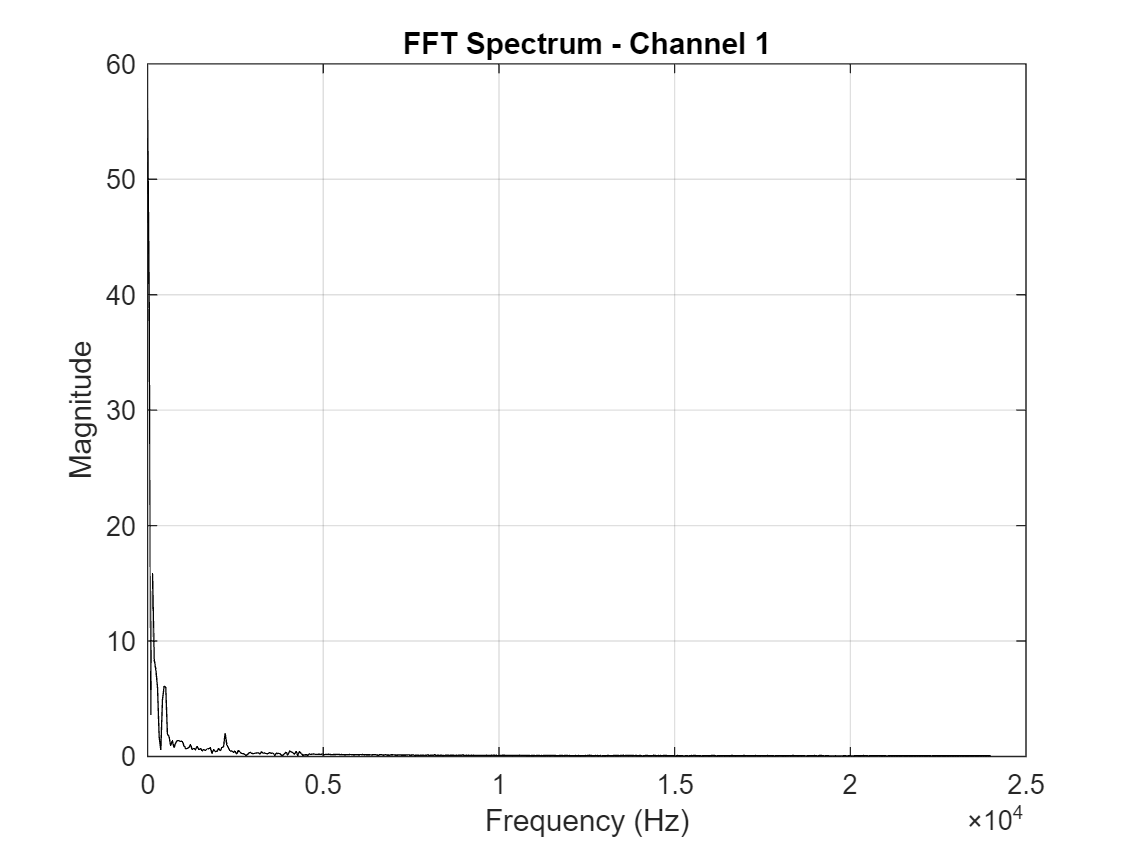


%%%% Load Audio File  %%%%
[y, Fs] = audioread(fnametest);
channelNum = 1; % Choose a channel from file to inspect
audioSegment = y(:, channelNum);

%%%% FFT Computation For Selected Channel  %%%%
fftSize = 1024;
Y = abs(fft(audioSegment, fftSize)); % Magnitude spectrum
Y = Y(1:fftSize/2); % Keep only positive frequencies
freqAxis = linspace(0, Fs/2, length(Y)); % Frequency axis

%%%% Plot FFT of Selected Channel  %%%%
figure;
plot(freqAxis, Y, 'k');
xlabel("Frequency (Hz)");
ylabel("Magnitude");
title(sprintf("FFT Spectrum - Channel %d", channelNum));
grid on;